clear all;
close all;

% Load preprocessed data from the previous step
fprintf('Loading preprocessed data from "Data/preprocessed_data.mat"...\n');

Loading preprocessed data from "Data/preprocessed_data.mat"...


%load data for finding the best hyperparameter using training Data
load('../Data/preprocessed_data.mat', 'trainingInputs', 'trainingTargets');
fprintf('Preprocessed data loaded successfully.\n');

Preprocessed data loaded successfully.


Define hyperparameter search space for Bayesian Optimization

fprintf('Defining hyperparameter space for Bayesian Optimization...\n');

Defining hyperparameter space for Bayesian Optimization...


% Define optimization variables for hyperparameter tuning

optimVars = [
    optimizableVariable('learningRate', [0.001, 0.1], 'Transform', 'log'),  % Continuous range for learning rate (log scale)
    optimizableVariable('momentum', [0.5, 0.9]),                           % Continuous range for momentum
    optimizableVariable('numLayers', [1, 3], 'Type', 'integer'),           % Integer range for the number of hidden layers
    optimizableVariable('numNeurons', [10, 50], 'Type', 'integer'),        % Integer range for neurons per layer
    optimizableVariable('epochs', [10, 50], 'Type', 'integer'),            % Integer range for the number of epochs
    optimizableVariable('activationFunction', {'logsig', 'tansig', 'purelin'}, 'Type', 'categorical'), % Activation function options
    optimizableVariable('performFcn', {'mse', 'crossentropy'}, 'Type', 'categorical'), % Performance function options
    optimizableVariable('trainingFunction', {'traingd', 'trainlm', 'trainbfg', 'trainrp', ... % Training functions
                                             'trainscg', 'traincgb', 'traincgf', 'traincgp', 'trainoss', 'traingdx'}, ...
                                             'Type', 'categorical')
];

% Initialize array to store training times for each evaluation
trainingTimes = []; 




% Run Bayesian Optimization with custom tracking of training time
fprintf('Starting Bayesian Optimization...\n'); 

Starting Bayesian Optimization...



% Run Bayesian optimization on the objective function with defined hyperparameters
results = bayesopt(@(optVars) objectiveFcn(optVars, trainingInputs, trainingTargets, trainingTimes), optimVars, ...
                   'MaxObjectiveEvaluations', 40, ...           % Set the number of optimization iterations to 60
                   'IsObjectiveDeterministic', false, ...       % Specify that results may vary across runs (non-deterministic)
                   'AcquisitionFunctionName', 'expected-improvement-plus', ... % Choose acquisition function to balance exploration and exploitation
                   'PlotFcn', []);                              % Disable automatic plotting for a custom approach

|===============================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | learningRate |     momentum |    numLayers |   numNeurons |       epochs | activationFu-|   performFcn | trainingFunc-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              | nction       |              | tion         |
|===============================================================================================================================================================================================|
|    1 | Best   |   0.0064783 |      29.543 |   0.0064783 |   0.0064783 |     0.032172 |      0.77721 |            3 |           40 |           35 |       tansig |          mse |      trainrp |
|    2 | Accept |     0.15075 


fprintf('Bayesian Optimization completed.\n');

Bayesian Optimization completed.




% Extract the best hyperparameters from the optimization results
bestParams = results.XAtMinObjective;

% Retrieve the trace of all hyperparameter combinations and their objective values
traceResults = results.XTrace;

% Save best hyperparameters
fprintf('Saving best hyperparameters to "Data/exp3/best_hyperparameters.mat"...\n');

Saving best hyperparameters to "Data/exp3/best_hyperparameters.mat"...


save('../Data/exp3/best_hyperparameters.mat', 'bestParams');
fprintf('Best hyperparameters saved successfully.\n');

Best hyperparameters saved successfully.



% Save the entire optimization trace for analysis
fprintf('Saving full optimization trace to "Data/exp3/optimization_trace.mat"...\n');

Saving full optimization trace to "Data/exp3/optimization_trace.mat"...


save('../Data/exp3/optimization_trace.mat', 'traceResults');
fprintf('Full optimization trace saved successfully.\n');

Full optimization trace saved successfully.



% Save the recorded training times for each evaluation
fprintf('Saving training times to "Data/exp3/training_times.mat"...\n');

Saving training times to "Data/exp3/training_times.mat"...


save('../Data/exp3/training_times.mat', 'trainingTimes');
fprintf('Training times saved successfully.\n');

Training times saved successfully.



% Save optimization progress plot
fprintf('Saving optimization progress plot to "outputs/exp3/optimization_progress.fig"...\n');

Saving optimization progress plot to "outputs/exp3/optimization_progress.fig"...


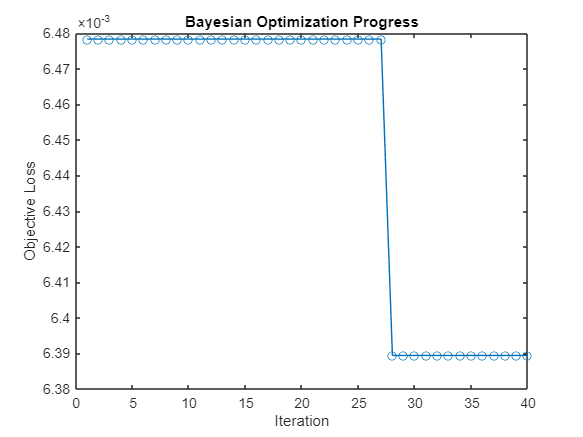

figure;
plot(results.ObjectiveMinimumTrace, '-o');
xlabel('Iteration');
ylabel('Objective Loss');
title('Bayesian Optimization Progress');
exportgraphics(gcf, '../outputs/exp3/optimization_progress.png', 'Resolution', 300);

fprintf('Optimization progress plot saved successfully.\n');

Optimization progress plot saved successfully.


function valError = objectiveFcn(optVars, trainingInputs, trainingTargets, trainingTimes)
    % Start timing the evaluation to record how long this evaluation takes
    evalStart = tic;

    % Set up the neural network based on the current hyperparameters
    hiddenLayerSize = repmat(optVars.numNeurons, 1, optVars.numLayers);  % Define the number of neurons in each hidden layer
    net = feedforwardnet(hiddenLayerSize);  % Initialize the neural network with the specified hidden layer structure
    
    % Convert categorical training function name to a character array for compatibility
    trainingFunction = char(optVars.trainingFunction);
    net.trainFcn = trainingFunction;  % Assign the selected training function to the network

    % Check compatibility of the selected training function with the performance function
    performFcn = char(optVars.performFcn);  % Convert performance function to character array
    incompatiblePairs = {
        'trainlm', 'crossentropy';  % trainlm is incompatible with cross-entropy
        'trainbr', 'crossentropy';  % trainbr is incompatible with cross-entropy
        'traingd', 'crossentropy';  % traingd is incompatible with cross-entropy
    };

    % Check if the current training and performance function pair is incompatible
    if any(strcmp(incompatiblePairs(:,1), trainingFunction) & strcmp(incompatiblePairs(:,2), performFcn))
        % If incompatible, skip this configuration by assigning a high error value
        valError = 1e6;
        % Record evaluation time for this configuration
        trainingTimes(end + 1) = toc(evalStart);  % Stop the timer and store the time
        return;  % Exit function without further processing
    end

    % Configure the network's hyperparameters from Bayesian Optimization
    net.trainParam.lr = optVars.learningRate;  % Set learning rate
    net.trainParam.mc = optVars.momentum;      % Set momentum for training
    net.trainParam.epochs = optVars.epochs;    % Set the number of epochs for training
    net.performFcn = performFcn;               % Assign the performance function (e.g., MSE or cross-entropy)
    net.divideFcn = 'divideind';               % Custom division of data for train, validate, test splits

    net.trainParam.max_fail = 6;               % Stop training after 6 consecutive epochs without improvement
    net.trainParam.showWindow = false;         % Disable training GUI window for efficiency

    % Apply the chosen activation function to each hidden layer
    for layer = 1:optVars.numLayers
        net.layers{layer}.transferFcn = char(optVars.activationFunction);  % Set activation function for each layer
    end

    % Define indices for train, validation, and test sets
    numSamples = size(trainingInputs, 2);
    trainIdx = 1:round(0.6 * numSamples);           % 60% for training
    valIdx = round(0.6 * numSamples) + 1:round(0.8 * numSamples);  % 20% for validation
    testIdx = round(0.8 * numSamples) + 1:numSamples;              % 20% for testing

    % Assign indices for data division
    net.divideParam.trainInd = trainIdx;
    net.divideParam.valInd = valIdx;
    net.divideParam.testInd = testIdx;

    % Train the network on the training set
    [net, tr] = train(net, trainingInputs, trainingTargets);

    % Calculate validation error on the validation set
    valOutputs = net(trainingInputs(:, valIdx));  % Run network predictions on validation data
    valError = perform(net, trainingTargets(:, valIdx), valOutputs);  % Calculate error (MSE or cross-entropy) on validation set

    % Stop timing and save the evaluation time for this configuration
    trainingTimes(end + 1) = toc(evalStart);
end


clear all;
close all;

% Load best hyperparameters from Bayesian Optimization
fprintf('Loading best hyperparameters from "Data/exp3/best_hyperparameters.mat"...\n');
load('../Data/exp3/best_hyperparameters.mat', 'bestParams');
fprintf('Best hyperparameters loaded successfully.\n');


% Load preprocessed data for testing
fprintf('Loading preprocessed data from "Data/preprocessed_data.mat"...\n');
load('../Data/preprocessed_data.mat', 'trainingInputs', 'trainingTargets');
fprintf('preprocessed data (training data) loaded successfully.\n');

disp(bestParams)


% Configure the network with the best hyperparameters
fprintf('Configuring neural network with best hyperparameters...\n');
bestHiddenLayerSize = repmat(bestParams.numNeurons, 1, bestParams.numLayers);  % Set number of layers and neurons
net = feedforwardnet(bestHiddenLayerSize);  % Initialize network with specified hidden layers

% Set training parameters
net.trainFcn = char(bestParams.trainingFunction);
net.performFcn = char(bestParams.performFcn);
net.trainParam.lr = bestParams.learningRate;
net.trainParam.mc = bestParams.momentum;
net.trainParam.epochs = bestParams.epochs;
net.divideFcn = 'dividetrain';  % Use all data without further internal split

% Set activation function for each layer
for layer = 1:bestParams.numLayers
    net.layers{layer}.transferFcn = char(bestParams.activationFunction);
end

Train the network on the entire training dataset

fprintf('Training the neural network with best hyperparameters...\n');
[net, tr] = train(net, trainingInputs, trainingTargets);
fprintf('Training completed.\n');


% save the plots which comes in the UI after training
% Save generated plots after training
fprintf('Saving generated plots...\n');

% Performance Plot
if isfield(tr, 'perf')
    figure, plotperform(tr);  % Generate the performance plot
    exportgraphics(gcf, '../outputs/exp3/performance_plot_best_observed.png', 'Resolution', 300);  % Save performance plot with high resolution
%    close(gcf);  % Close the figure after saving
end

% Training State Plot
if isfield(tr, 'states')
    figure, plottrainstate(tr);  % Generate the training state plot
    exportgraphics(gcf, '../outputs/exp3/training_state_plot_best_observed.png', 'Resolution', 300);  % Save training state plot with high resolution
 %   close(gcf);
end

fprintf('All plots saved successfully.\n');


% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/exp3/training_progress_best_observed.png"...\n');
figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/exp3/training_progress_best_observed.png', 'Resolution', 300);
close(gcf);  % Close the figure after saving
fprintf('Training progress plot saved successfully.\n');



% Save the trained network and training record
fprintf('Saving trained model to "Data/exp3/final_model.mat"...\n');
save('../Data/exp3/final_model.mat', 'net', 'tr');
fprintf('Trained model saved successfully.\n');



% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/training_progress.png"...\n');
figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/exp3/training_progress.png', 'Resolution', 300);

fprintf('Training progress plot saved successfully as PNG.\n');

clear all;
close all;

% Load trained model and test data
fprintf('Loading trained model from "Data/exp3/final_model.mat"...\n');
load('../Data/exp3/final_model.mat', 'net');
fprintf('Trained model loaded successfully.\n');

fprintf('Loading test data from "Data/exp3/preprocessed_data.mat"...\n');
load('../Data/exp3/preprocessed_data.mat', 'testInputs', 'testTargets');
fprintf('Test data loaded successfully.\n');



% Perform predictions on the test data
fprintf('Predicting on the test data...\n');
predictedTestOutputs = net(testInputs);  % Raw outputs from network
predictedTestLabels = predictedTestOutputs >= 0.5;  % Convert to binary labels (assuming threshold of 0.5)

% Ensure both testTargets and predictedTestLabels are of type double
testTargets = double(testTargets);
predictedTestLabels = double(predictedTestLabels);

% Calculate accuracy
numCorrect = sum(predictedTestLabels == testTargets);
accuracy = numCorrect / length(testTargets) * 100;
fprintf('Accuracy on Test Data: %.2f%%\n', accuracy);

% Save accuracy in a text file
metricsFile = fopen('../outputs/exp3/metrics.txt', 'w');
fprintf(metricsFile, 'Accuracy on Test Data: %.2f%%\n', accuracy);
fclose(metricsFile);

% Confusion Matrix
fprintf('Generating confusion matrix...\n');
confMat = confusionmat(testTargets, predictedTestLabels);


% Display the confusion matrix using confusionchart
figure;
cm = confusionchart(confMat);

% Set properties to show numbers without scientific notation
cm.CellLabelFormat = '%d';  % Format labels as integers

% Customize the chart title and labels as needed
cm.Title = 'Confusion Matrix';
cm.XLabel = 'Predicted Labels';
cm.YLabel = 'True Labels';

% Save the confusion matrix plot as a high-resolution PNG file
exportgraphics(gcf, '../outputs/exp3/confusion_matrix.png', 'Resolution', 300);
fprintf('Confusion matrix saved as "../outputs/confusion_matrix.png" with high resolution.\n');



% Calculate additional metrics (Precision, Recall, F1 Score)
truePositives = sum(predictedTestLabels == 1 & testTargets == 1);
trueNegatives = sum(predictedTestLabels == 0 & testTargets == 0);
falsePositives = sum(predictedTestLabels == 1 & testTargets == 0);
falseNegatives = sum(predictedTestLabels == 0 & testTargets == 1);

precision = truePositives / (truePositives + falsePositives);
recall = truePositives / (truePositives + falseNegatives);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);
fprintf('Recall: %.2f%%\n', recall * 100);
fprintf('F1 Score: %.2f%%\n', f1Score * 100);

% Save additional metrics
metricsFile = fopen('../outputs/exp3/metrics.txt', 'a');  % Open in append mode
fprintf(metricsFile, 'Precision: %.2f%%\n', precision * 100);
fprintf(metricsFile, 'Recall: %.2f%%\n', recall * 100);
fprintf(metricsFile, 'F1 Score: %.2f%%\n', f1Score * 100);
fclose(metricsFile);

% ROC Curve and AUC
fprintf('Generating ROC curve...\n');
[X, Y, T, AUC] = perfcurve(testTargets, predictedTestOutputs, 1);
figure;
plot(X, Y, '-b', 'LineWidth', 1.5);
hold on;
plot([0 1], [0 1], '--k');  % Diagonal line for random guessing
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ', num2str(AUC), ')']);
grid on;
% Save the ROC curve as a high-resolution PNG file
exportgraphics(gcf, '../outputs/exp3/roc_curve.png', 'Resolution', 300);
fprintf('ROC curve saved as "../outputs/exp3/roc_curve.png" with high resolution.\n');
